clear all, close all, clc

syms u1 u2 m I L g
syms x1 x1d x1dd
syms x2 x2d x2dd 
syms x3 x3d x3dd

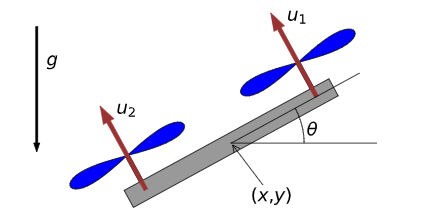

Las ecuaciones del modelo:

eq1 = -(u1+u2)*sin(x3)-m*x1dd

$$eq1 = -m\,\mathrm{x1dd}-\sin\left(x_{3}\right)\,\left(u_{1}+u_{2}\right)$$

eq2 = (u1+u2)*cos(x3)-m*g-m*x2dd

$$eq2 = \cos\left(x_{3}\right)\,\left(u_{1}+u_{2}\right)-m\,\mathrm{x2dd}-g\,m$$

eq3 = L*(u1-u2)-I*x3dd

$$eq3 = L\,\left(u_{1}-u_{2}\right)-\text{I}\,\mathrm{x3dd}$$

Resolver las ecuaciones:

Sol = solve([eq1,eq2,eq3],[x1dd,x2dd,x3dd]);
Sol.x1dd = simplify(Sol.x1dd);
Sol.x2dd = simplify(Sol.x2dd);
Sol.x3dd = simplify(Sol.x3dd);

Obtener el modelo de espacio de estados.

syms y1 y2 y3 y4 y5 y6

fx1 = y1

$$fx1 = y_{1}$$

fx2 = subs(Sol.x1dd,{x1,x1d,x2,x2d,x3,x3d},{y1,y2,y3,y4,y5,y6})

$$fx2 = -\frac{\sin\left(y_{5}\right)\,\left(u_{1}+u_{2}\right)}{m}$$

fx3 = y3

$$fx3 = y_{3}$$

fx4 = subs(Sol.x2dd,{x1,x1d,x2,x2d,x3,x3d},{y1,y2,y3,y4,y5,y6})

$$fx4 = \frac{u_{1}\,\cos\left(y_{5}\right)-g\,m+u_{2}\,\cos\left(y_{5}\right)}{m}$$

fx5 = y5

$$fx5 = y_{5}$$

fx6 = subs(Sol.x3dd,{x1,x1d,x2,x2d,x3,x3d},{y1,y2,y3,y4,y5,y6})

$$fx6 = \frac{L\,\left(u_{1}-u_{2}\right)}{\text{I}}$$


F = [fx1;fx2;fx3;fx4;fx5;fx6]

$$F = \left(\begin{array}{c} y_{1}\\ -\frac{\sin\left(y_{5}\right)\,\left(u_{1}+u_{2}\right)}{m}\\ y_{3}\\ \frac{u_{1}\,\cos\left(y_{5}\right)-g\,m+u_{2}\,\cos\left(y_{5}\right)}{m}\\ y_{5}\\ \frac{L\,\left(u_{1}-u_{2}\right)}{\text{I}} \end{array}\right)$$

Calculamos los jacobianos en los puntos de equilibrio para hallar la linealización del sistema:

A_symbolic = jacobian(F, [y1,y2,y3,y4,y5,y6])

$$A\_symbolic = \left(\begin{array}{cccccc} 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & -\frac{\cos\left(y_{5}\right)\,\left(u_{1}+u_{2}\right)}{m} & 0\\ 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & -\frac{u_{1}\,\sin\left(y_{5}\right)+u_{2}\,\sin\left(y_{5}\right)}{m} & 0\\ 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

B_symbolic = jacobian(F, [u1,u2,])

$$B\_symbolic = \left(\begin{array}{cc} 0 & 0\\ -\frac{\sin\left(y_{5}\right)}{m} & -\frac{\sin\left(y_{5}\right)}{m}\\ 0 & 0\\ \frac{\cos\left(y_{5}\right)}{m} & \frac{\cos\left(y_{5}\right)}{m}\\ 0 & 0\\ \frac{L}{\text{I}} & -\frac{L}{\text{I}} \end{array}\right)$$

Ahora calculamos los valores algebraicos del modelo, para encontrar los valores numericos del sistema:

A = subs(A_symbolic,{m,I,L,g,y1,y2,y3,y4,y5,y6, u1,u2}, ...
     [sym(0.1393) sym(0.0002) sym(0.245) sym(9.81) sym(0) sym(0) sym(0) sym(0) sym(0) sym(0) sym(1) sym(1)]);

B = subs(B_symbolic,{m,I,L,g, y1,y2,y3,y4,y5,y6}, ...
     [sym(0.1393) sym(0.0002) sym(0.245) sym(9.81) sym(0) sym(0) sym(0) sym(0) sym(0) sym(0)]);



%%L =24.5 cm ===== 0.245 m
A = eval(A)

A =     1.0000         0         0         0         0         0
         0         0         0         0  -14.3575         0
         0         0    1.0000         0         0         0
         0         0         0         0         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0         0


B = eval(B)

B = 1.0e+03 *

         0         0
         0         0
         0         0
    0.0072    0.0072
         0         0
    1.2250   -1.2250



sz =  size(B)

sz =      6     2


D = zeros(sz)

D =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0


C = eye(6)

C =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1


Sys1 = ss(A,B,C,D)

Sys1 =
 
  A = 
           x1      x2      x3      x4      x5      x6
   x1       1       0       0       0       0       0
   x2       0       0       0       0  -14.36       0
   x3       0       0       1       0       0       0
   x4       0       0       0       0       0       0
   x5       0       0       0       0       1       0
   x6       0       0       0       0       0       0
 
  B = 
          u1     u2
   x1      0      0
   x2      0      0
   x3      0      0
   x4  7.179  7.179
   x5      0      0
   x6   1225  -1225
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   1   0   0   0   0
   y3   0   0   1   0   0   0
   y4   0   0   0   1   0   0
   y5   0   0   0   0   1   0
   y6   0   0   0   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
   y4   0   0
   y5   0   0
   y6   0   0
 
Continuous-time state-space model.



% Convertirl modelo a función de transferencia


La función de tranferencia del sistema será

m = 0.1393; L = 0.0245;
I = (m/12)*L^2;
U_n = 1;

num = [L*U_n];
den = [I 0 0];

G_s = tf(num,den)

G_s =
 
     0.0245
  -------------
  6.968e-06 s^2
 
Continuous-time transfer function.
Model Properties


La simulación del sistema en lazo abierto si la entrada es un escalón se muestra a continuación:

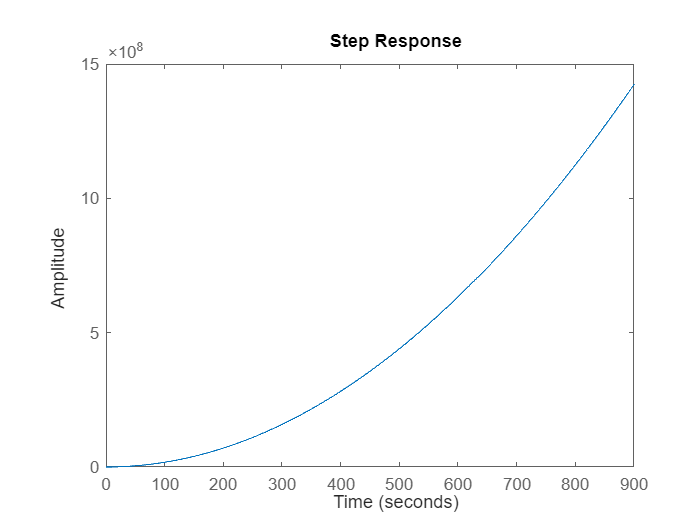

step(G_s)

El lugar geometrico de las raices es:

pole(G_s)

ans =      0
     0


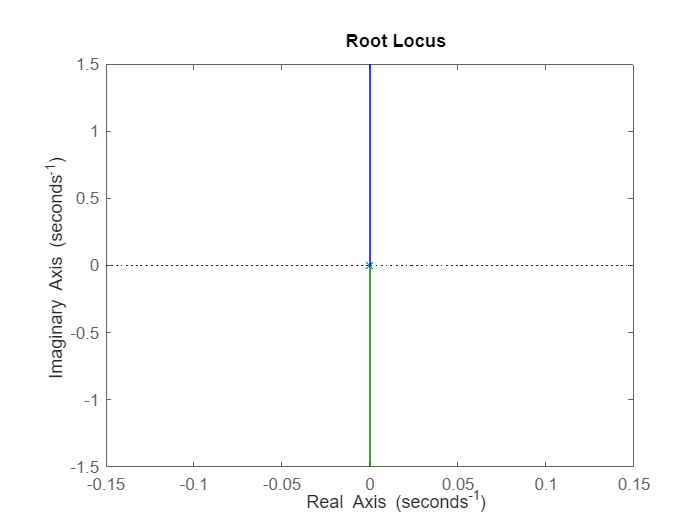

rlocus(G_s)

Para discretizar se requiere un tiempo de muestreo que contiene la siguiente formula: $T_m = \frac{2 \pi}{20 p_m} $ donde $P_m
$ es el polo más a la izquierda en el lugar geometrico de las raices. Dado que ambos polos del sistema en lazo abierto es 0, se escoge un valor de un polo muy rapido (A la izquierda) adecuado para encontrar el tiempo de muesteo:

Tm = 2*pi/(20)

Tm = 0.3142

Para discretizar utilizamos el comando c2d:

G_dis = c2d(G_s,Tm)

G_dis =
 
  173.5 z + 173.5
  ---------------
   z^2 - 2 z + 1
 
Sample time: 0.31416 seconds
Discrete-time transfer function.
Model Properties


Graficamos el sistema discreto en lazo abierto:

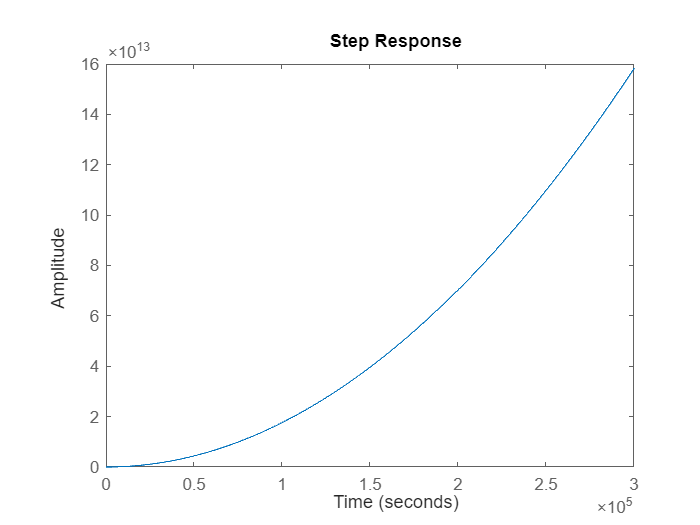

step(G_dis)

El modelo de variables de estado discreto se haya de la siguiente manera:

[Adis,Bdis,Cdis,Ddis] = tf2ss(cell2mat(G_dis.Numerator),cell2mat(G_dis.Denominator))

Adis =      2    -1
     1     0


Bdis =      1
     0


Cdis =   173.5137  173.5137


Ddis = 0

 La respuesta al escalón:

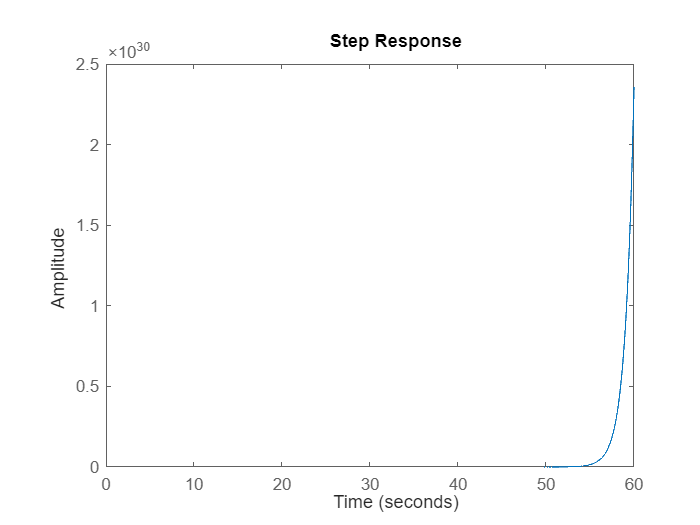

Sys2 = ss(Adis, Bdis,Cdis,Ddis);
step(Sys2)